## Image morphological processing :

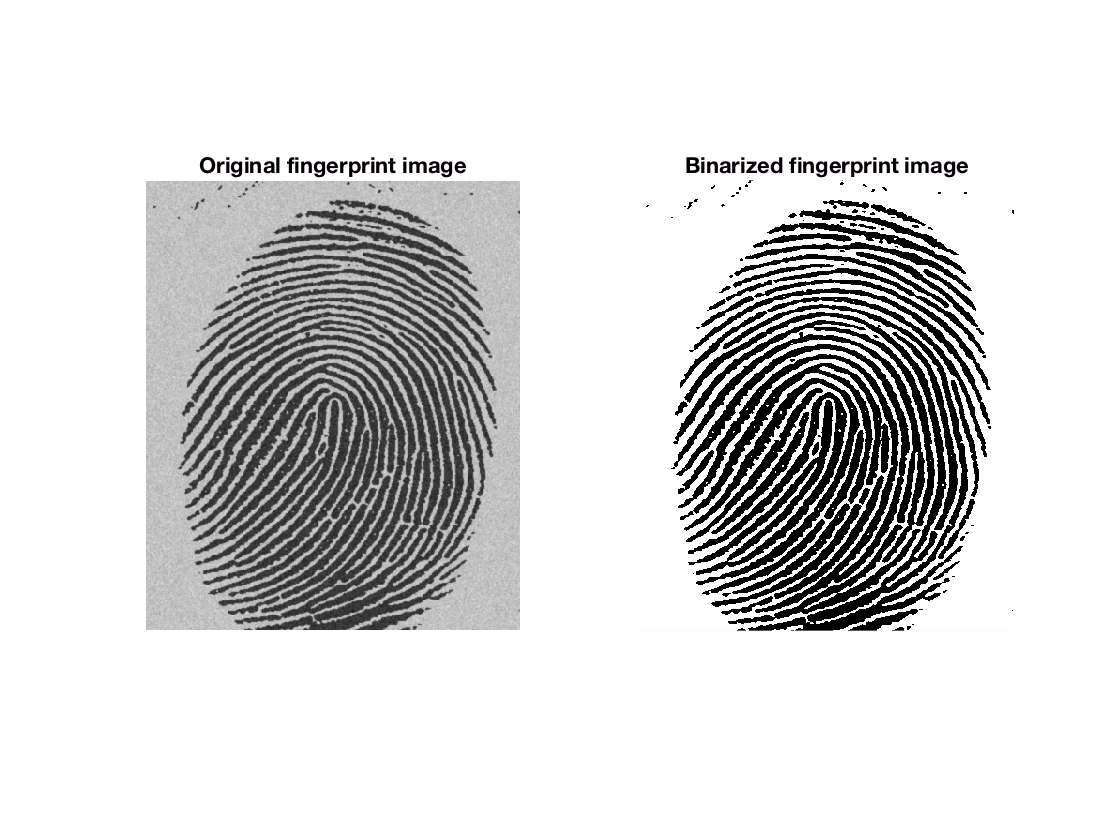

sourceImg = imread('noisy_fingerprint.tif');
subplot(1, 2, 1), imshow(sourceImg);
title('Original fingerprint image');

%==============================================================

bwImg = imbinarize(sourceImg);
subplot(1, 2, 2), imshow(bwImg);
title('Binarized fingerprint image');

- Image erosion

clf
se = strel('cube', 5);
img_erosion = imerode(bwImg, se);

subplot(1, 2, 1), imshow(img_erosion);
title('Eroded fingerprint image');

- Image dilation

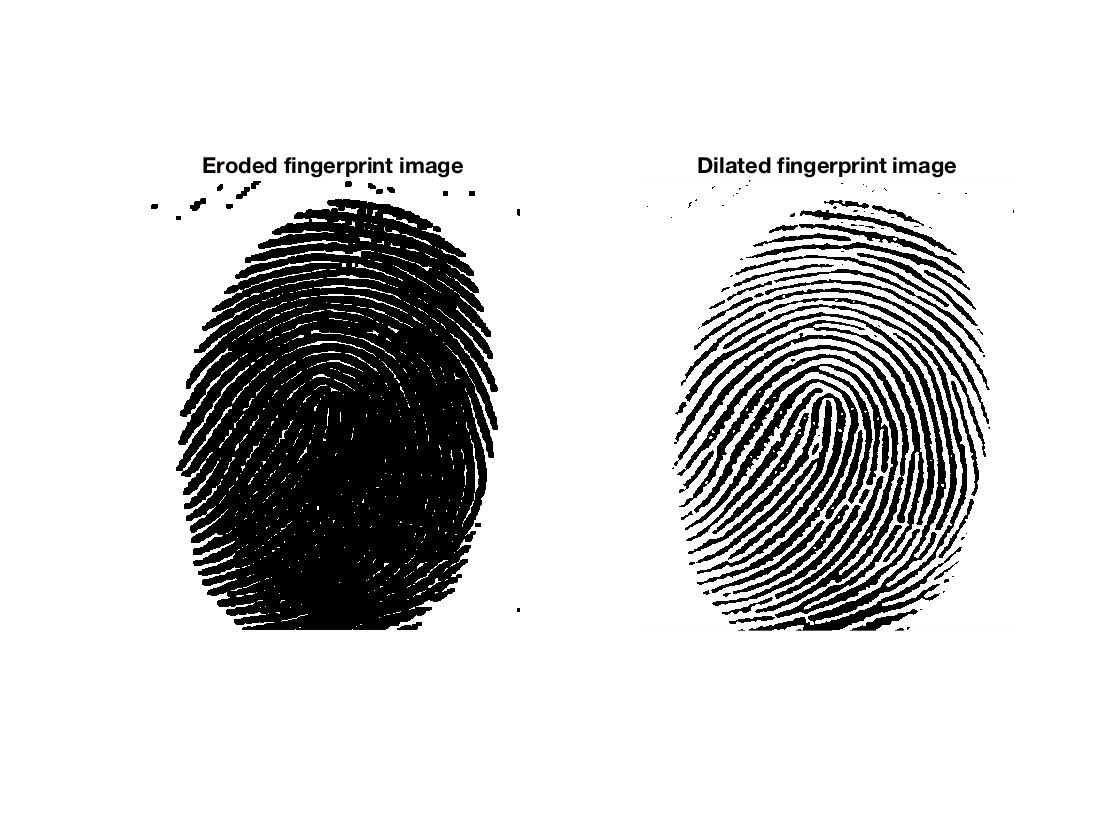

dilation_matrix = [0, 1, 0;
                   1, 0, 1;
                   0, 1, 0];
img_dilation = imdilate(bwImg, dilation_matrix);
subplot(1, 2, 2), imshow(img_dilation);
title('Dilated fingerprint image');

- Image opening

clf
img_opening = imopen(bwImg, se);
subplot(1, 2, 1), imshow(img_opening);
title('Opened fingerprint image');

- Image closing

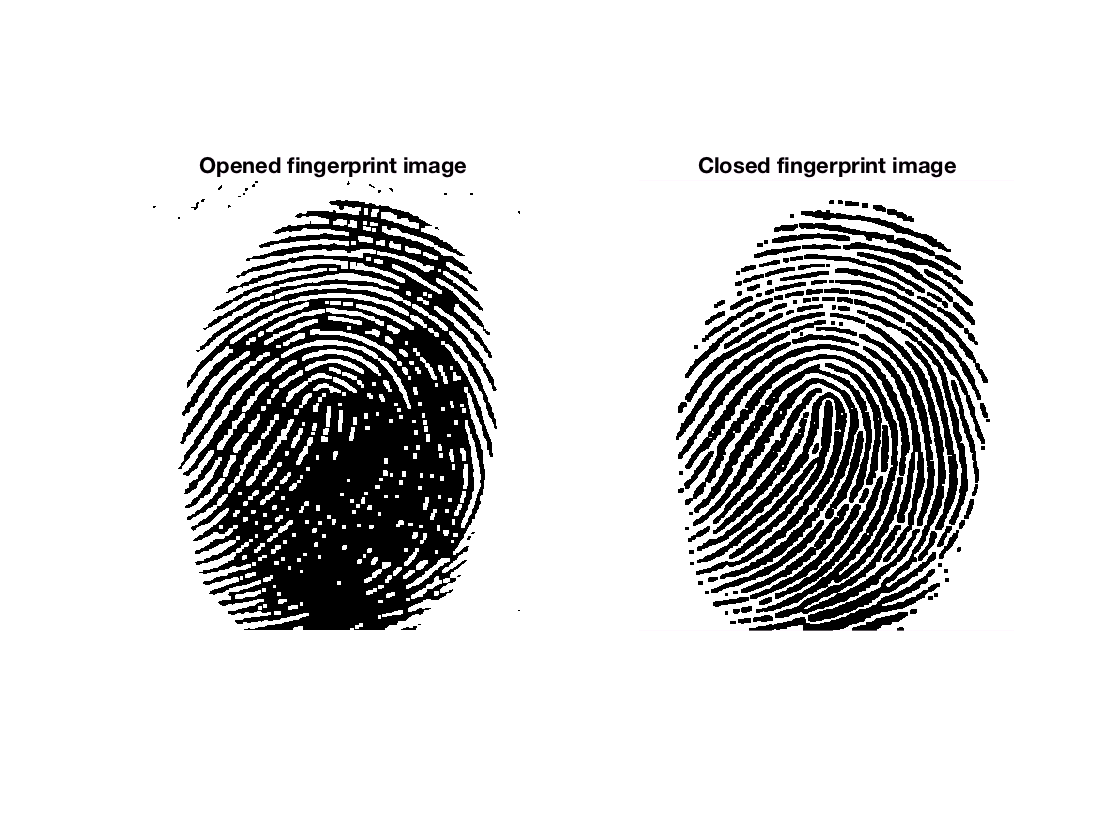

img_closing = imclose(bwImg, se);
subplot(1, 2, 2), imshow(img_closing);
title('Closed fingerprint image');